clc, close all, clear all

# Data Exploration

## Data Loading

% [~, turbine_idx]= xlsfinfo('data.xlsx');
% nWTs = numel(turbine_idx);
% X = cell(1, nWTs);
% 
% for k=1:nWTs
%   x = xlsread('data.xlsx', turbine_idx{k});
%   X{k}= x(2:end,:);
% end
% 
% % Create label vector with binary values representing faulty 
% % (1 denotes faulty functioning, 0 denotes normal functioning)
% Y = [0, 1, 1, 1];
% 
% % Save data
% save X.mat X
% save turbine_idx.mat turbine_idx
% save Y.mat Y

load X.mat
load Y.mat
load turbine_idx.mat

## Data Exploratory

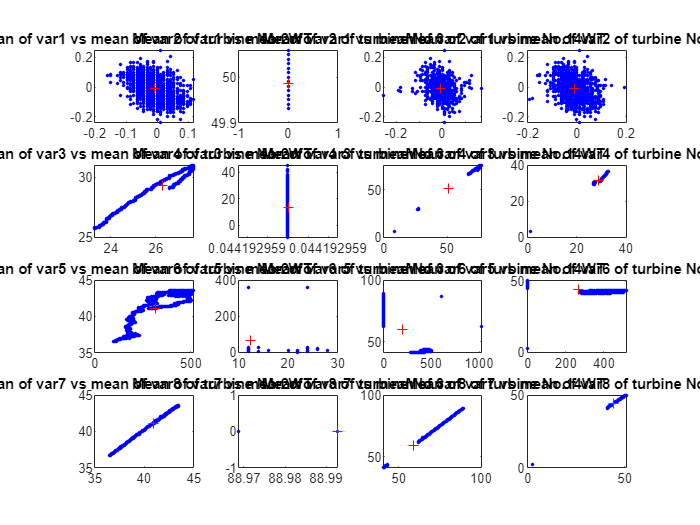

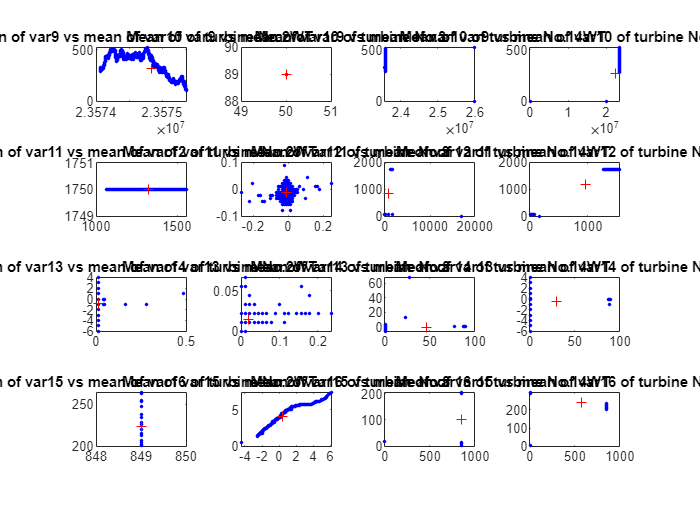

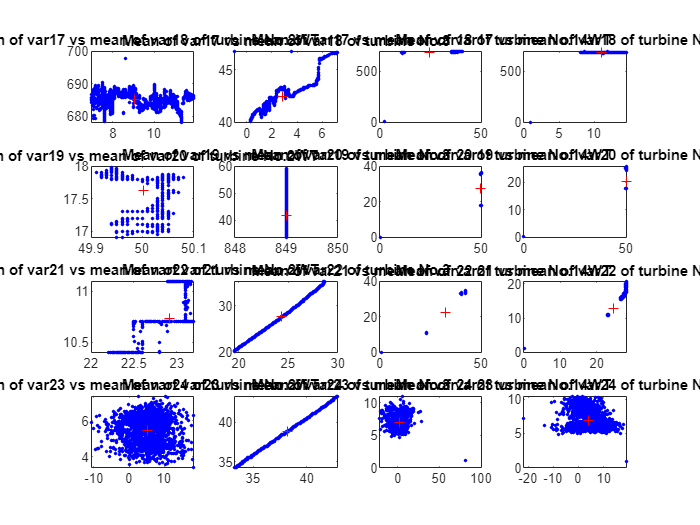

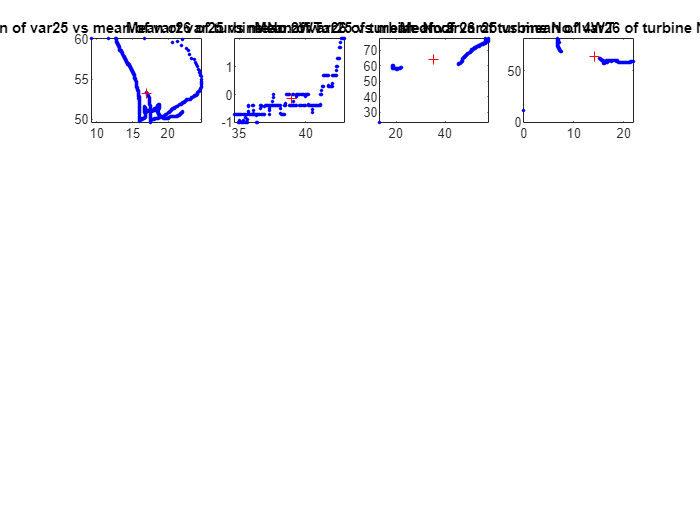

nWTs = numel(turbine_idx);

% Define rWTs vector storing no of observations (number of rows);
% cWTs vector storing no of variables (number of columns);
% meanWTs cell array storing mean values of feature data (mean value of each column);
% minWTs cell array storing minimum values of feature data (minimum value of each column);
% maxWTs cell array storing maximum values of feature data (maximum value of each column);
% stdWTs cell array storing standard deviation values of feature data
% (standard deviation value of each column) of all turbines' dataset;
rWTs = zeros(nWTs, 1);
cWTs = zeros(nWTs, 1);
meanWTs = cell(nWTs, 1);
minWTs = cell(nWTs, 1);
maxWTs = cell(nWTs, 1);
stdWTs = cell(nWTs, 1);

for k=1:nWTs
    [rWTs(k), cWTs(k)] = size(X{k});
    meanWTs{k} = mean(X{k});
    minWTs{k} = min(X{k});
    maxWTs{k} = max(X{k});
    stdWTs{k} = std(X{k});
end

% Plots of data and means to determine unhealthy turbine data to drop

subplot_idx = reshape(1:nWTs*4, nWTs, 4)';
count = 1;
enough = false;
for i=0:4:28
    figure;
    for r=1:4
        if (count > 27 || count + 1 > 27)
            enough = true;
            break
        end
        for k=1:nWTs
            subplot(4,nWTs,subplot_idx(r,k));
            plot(X{k}(:,count), X{k}(:,count+1), '.b'), hold on;
            plot(meanWTs{k}(count), meanWTs{k}(count+1), 'r+'), hold off;
            title_text = sprintf('Mean of var%d vs mean of var%d of turbine %s', count, count+1, turbine_idx{k});
            title(title_text);
        end
        count = count + 2;
    end
    if (enough)
        break
    end
end 

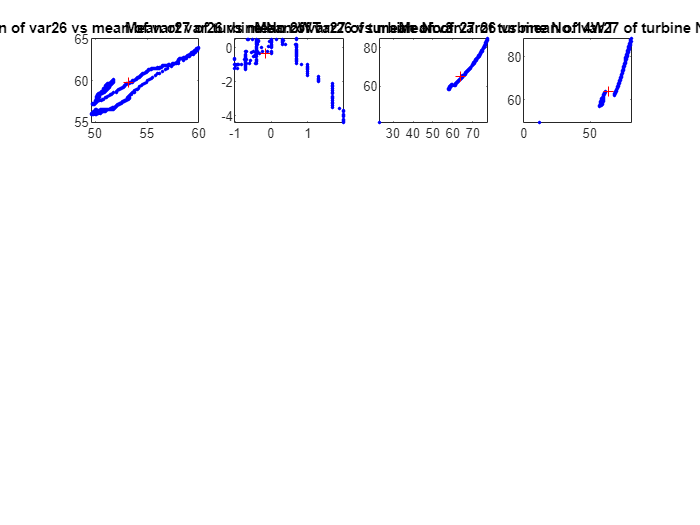


figure;
for k = 1:4
    subplot(4,nWTs,k);
    plot(X{k}(:,26), X{k}(:,26+1), '.b'), hold on;
    plot(meanWTs{k}(26), meanWTs{k}(26+1), 'r+'), hold off;
    title_text = sprintf('Mean of var%d vs mean of var%d of turbine %s', 26, 26+1, turbine_idx{k});
    title(title_text);
end

## Decision Making on fault and redundant data removal

Decision has been made to exclude the entire dataset belonging to the turbine No.3 (which is X{2}) due to fault data, and to also remove the last variable var28 of the dataset belonging to turbine No.2WT (which is X{1}(:,end)) due to redundancy and inconsistency.

Explanation on the decisions has been discussed in the report. Z holds data with faulty data excluded per decisions.

Z = {X{1}(:,1:end-1); X{3}; X{4}};
class_Z = Y([1, 3, 4]);

chosen_turbine_idx = turbine_idx([1, 3, 4]);
% save Z.mat Z
% save class_Z.mat class_Z

load Z.mat
load class_Z.mat

### Univariate analysis

% % Data distribution
% subplot_idx = reshape(1:16, 4, 4)';
% count = 1;
% enough = false;
% for i=0:4:28
%     figure;
%     for r=1:4
%         if (count > 27 || count + 1 > 27)
%             enough = true;
%             break
%         end
%         for k=1:nWTs
%             subplot(4,nWTs,subplot_idx(r,k));
%             histogram(X{k}(:,count));
%             title_text = sprintf('Histogram of var%d of turbine %s', count, turbine_idx{k});
%             title(title_text);
%         end
%         count = count + 1;
%     end
%     if (enough)
%         if (count == 27)
%             for k=1:nWTs
%             subplot(4,nWTs,subplot_idx(r,k));
%             histogram(X{k}(:,count));
%             title_text = sprintf('Histogram of var%d of turbine %s', count, turbine_idx{k});
%             title(title_text);
%             end
%         end
%         break
%     end
% end


### Multivariate analysis

% % Correlation between the features for each wind-turbine
% Xcorr = cell(nWTs, 1);
% for k=1:nWTs
%     Xcorr{k} = corr(X{k});
%     figure;
%     imagesc(Xcorr{k}),colorbar;
%     axis equal;
%     axis tight;
%     title_text = sprintf('Data correlation colormap of turbine %s', turbine_idx{k});
%     title(title_text);
% end
% 
% % Boxplot of each feature of the wind-turbine
% for k=1:nWTs
%     figure;
%     boxplot(X{k});
%     title_text = sprintf('Box plot data of turbine %s', turbine_idx{k});
%     title(title_text);
% end
% 
% % Scatterplot matrix for all the sensors from each wind-turbine
% for k=1:nWTs
%     figure;
%     plotmatrix(X{k});
%     title_text = sprintf('Scatter plot matrix of turbine %s', turbine_idx{k});
%     title(title_text);
% end



## Data Pretreatment

#### Recompute mean, min, max, std of chosen wind turbine data

chosen_nWTs = numel(chosen_turbine_idx);
chosen_rWTs = zeros(chosen_nWTs, 1);
chosen_cWTs = zeros(chosen_nWTs, 1);
chosen_meanWTs = cell(chosen_nWTs, 1);
chosen_minWTs = cell(chosen_nWTs, 1);
chosen_maxWTs = cell(chosen_nWTs, 1);
chosen_stdWTs = cell(chosen_nWTs, 1);

for k=1:chosen_nWTs
    [chosen_rWTs(k), chosen_cWTs(k)] = size(Z{k});
    chosen_meanWTs{k} = mean(Z{k});
    chosen_minWTs{k} = min(Z{k});
    chosen_maxWTs{k} = max(Z{k});
    chosen_stdWTs{k} = std(Z{k});
end


### 1. Find missing values

missing_values = [];
for i = 1:size(Z)
    fprintf('Indices of missing values of Turbine %s', chosen_turbine_idx{i})
    missing_val = ismissing(Z{i});
    [missing_obs, missing_var] = find(missing_val==1)
    if (numel(missing_obs)==0)
        fprintf('There is no missing values in the dataset of Turbine %s', chosen_turbine_idx{i});
    else
        missing_turbine_idx = i;
        missing_obs_idx = missing_obs;
        missing_var_idx = missing_var;
        missing_values = [missing_values; missing_turbine_idx, missing_obs_idx, missing_var_idx]
        fprintf('There is %d missing values in the dataset of Turbine %s', numel(missing_var), chosen_turbine_idx{i});
    end
end

Indices of missing values of Turbine No.2WT


missing_obs =

  0×1 empty double column vector


missing_var =

  0×1 empty double column vector



There is no missing values in the dataset of Turbine No.2WT

Indices of missing values of Turbine No.14WT

missing_obs = 358

missing_var = 9

missing_values =      2   358     9


There is 1 missing values in the dataset of Turbine No.14WT

Indices of missing values of Turbine No.39WT


missing_obs =

  0×1 empty double column vector


missing_var =

  0×1 empty double column vector



There is no missing values in the dataset of Turbine No.39WT


% remove 1 observation having missing value of turbine 14
Z{missing_values(1)}(missing_values(2), :) = [];

% recheck
for i = 1:size(Z)
    fprintf('Indices of missing values of Turbine %s', chosen_turbine_idx{i})
    missing_val = ismissing(Z{i});
    [missing_obs, missing_var] = find(missing_val==1)
    if (numel(missing_obs)==0)
        fprintf('There is no missing values in the dataset of Turbine %s', chosen_turbine_idx{i});
    else
        missing_turbine_idx = i;
        missing_obs_idx = missing_obs;
        missing_var_idx = missing_var;
        missing_values = [missing_values; missing_turbine_idx, missing_obs_idx, missing_var_idx]
        fprintf('There is %d missing values in the dataset of Turbine %s', numel(missing_var), chosen_turbine_idx{i});
    end
end

Indices of missing values of Turbine No.2WT


missing_obs =

  0×1 empty double column vector


missing_var =

  0×1 empty double column vector



There is no missing values in the dataset of Turbine No.2WT

Indices of missing values of Turbine No.14WT


missing_obs =

  0×1 empty double column vector


missing_var =

  0×1 empty double column vector



There is no missing values in the dataset of Turbine No.14WT

Indices of missing values of Turbine No.39WT


missing_obs =

  0×1 empty double column vector


missing_var =

  0×1 empty double column vector



There is no missing values in the dataset of Turbine No.39WT

### 2. Downsampling (requires Signal Processing Toolbox)

#### Downsampling rate selection based on mean values

chosen_meanWTs_mat = [chosen_meanWTs{1}; chosen_meanWTs{2}; chosen_meanWTs{3}];
offset = 0;
down_meanWTs_test = [];
down_meanWTs_test_diff = cell(6, 1);
for factor = 2:6
    fprintf('Max mean different when downsampling by factor = %d', factor);
    down_Z_test = cell(numel(class_Z), 1);
    for i = 1:size(Z)
        down_Z_test{i} = downsample(Z{i}, factor, offset);
        down_meanWTs_test(i,:) = mean(down_Z_test{i});
    end
    down_meanWTs_test_diff{factor} = down_meanWTs_test - chosen_meanWTs_mat;
    max_mean_diff = max(abs(down_meanWTs_test_diff{factor}),[],'all')
    observations_reduced_by_times = factor
end

Max mean different when downsampling by factor = 2

max_mean_diff = 1.5081e+04

observations_reduced_by_times = 2

Max mean different when downsampling by factor = 3

max_mean_diff = 1.3386e+04

observations_reduced_by_times = 3

Max mean different when downsampling by factor = 4

max_mean_diff = 1.1693e+04

observations_reduced_by_times = 4

Max mean different when downsampling by factor = 5

max_mean_diff = 1.4227e+04

observations_reduced_by_times = 5

Max mean different when downsampling by factor = 6

max_mean_diff = 8.3145e+03

observations_reduced_by_times = 6

fprintf('The downsampling factor of 4 has been chosen for the first try.')

The downsampling factor of 4 has been chosen for the first try.

#### Downsampling with chosen rate of 4 (NOT FINAL DECISION)

%downsampling_factor = 1;
%downsampling_factor = 2;
%downsampling_factor = 3;
downsampling_factor = 4;
down_Z = cell(numel(class_Z), 1);

for i = 1:size(Z)
    down_Z{i} = downsample(Z{i}, downsampling_factor, offset);
end

#### Compute mean, min, max, std of downsampled chosen wind turbine data

down_rWTs = zeros(chosen_nWTs, 1);
down_cWTs = zeros(chosen_nWTs, 1);
down_meanWTs = cell(chosen_nWTs, 1);
down_minWTs = cell(chosen_nWTs, 1);
down_maxWTs = cell(chosen_nWTs, 1);
down_stdWTs = cell(chosen_nWTs, 1);

for k=1:chosen_nWTs
    [down_rWTs(k), down_cWTs(k)] = size(down_Z{k});
    down_meanWTs{k} = mean(down_Z{k});
    down_minWTs{k} = min(down_Z{k});
    down_maxWTs{k} = max(down_Z{k});
    down_stdWTs{k} = std(down_Z{k});
end

#### Plots of data and means of original data and downsampled data

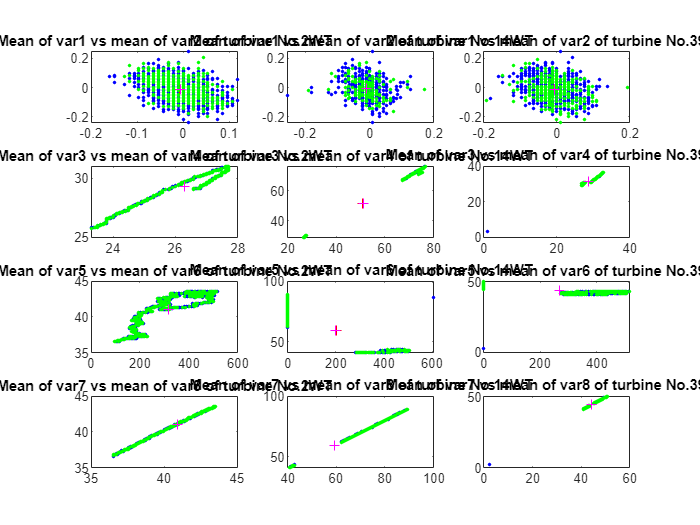

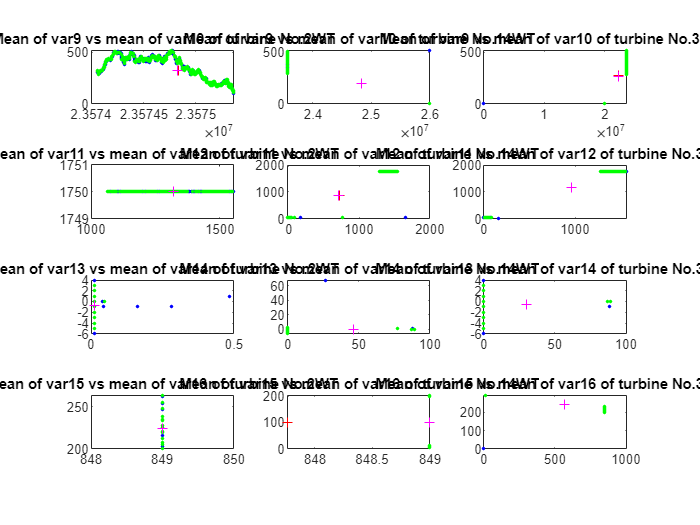

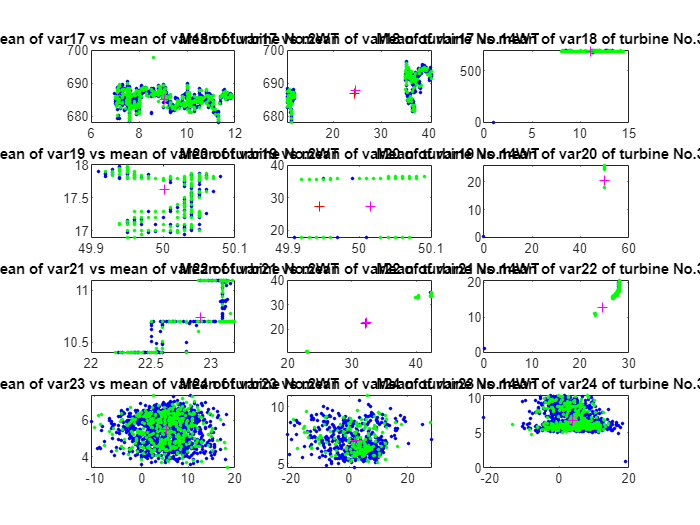

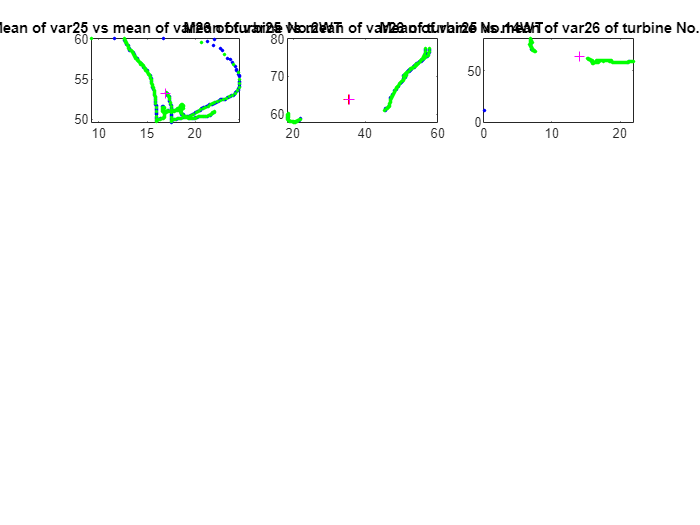

subplot_idx = reshape(1:chosen_nWTs*4, chosen_nWTs, 4)';
count = 1;
enough = false;
for i=0:4:28
    figure;
    for r=1:4
        if (count > 27 || count + 1 > 27)
            enough = true;
            break
        end
        for k=1:chosen_nWTs
            subplot(4,chosen_nWTs,subplot_idx(r,k));
            plot(Z{k}(:,count), Z{k}(:,count+1), '.b'), hold on;
            plot(chosen_meanWTs{k}(count), chosen_meanWTs{k}(count+1), 'r+');
            plot(down_Z{k}(:,count), down_Z{k}(:,count+1), '.g');
            plot(down_meanWTs{k}(count), down_meanWTs{k}(count+1), 'm+'), hold off;
            title_text = sprintf('Mean of var%d vs mean of var%d of turbine %s', count, count+1, chosen_turbine_idx{k});
            title(title_text);
        end
        count = count + 2;
    end
    if (enough)
        break
    end
end 

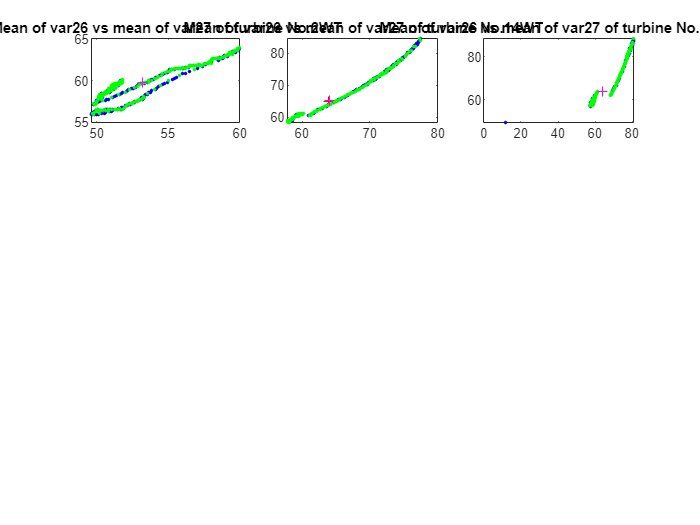


count = 26;
figure;
for k = 1:chosen_nWTs
    subplot(4,chosen_nWTs,k);
    plot(Z{k}(:,count), Z{k}(:,count+1), '.b'), hold on;
    plot(chosen_meanWTs{k}(count), chosen_meanWTs{k}(count+1), 'r+');
    plot(down_Z{k}(:,count), down_Z{k}(:,count+1), '.g');
    plot(down_meanWTs{k}(count), down_meanWTs{k}(count+1), 'm+'), hold off;
    title_text = sprintf('Mean of var%d vs mean of var%d of turbine %s', count, count+1, chosen_turbine_idx{k});
    title(title_text);
end


% Recheck missing values
for i = 1:size(down_Z)
    fprintf('Indices of missing values of Turbine %s', chosen_turbine_idx{i})
    missing_val = ismissing(down_Z{i});
    [missing_obs, missing_var] = find(missing_val==1)
    if (numel(missing_obs)==0)
        fprintf('There is no missing values in the dataset of Turbine %s', chosen_turbine_idx{i});
    else
        fprintf('There is %d missing values in the dataset of Turbine %s', numel(missing_var), chosen_turbine_idx{i});
    end
end

Indices of missing values of Turbine No.2WT


missing_obs =

  0×1 empty double column vector


missing_var =

  0×1 empty double column vector



There is no missing values in the dataset of Turbine No.2WT

Indices of missing values of Turbine No.14WT


missing_obs =

  0×1 empty double column vector


missing_var =

  0×1 empty double column vector



There is no missing values in the dataset of Turbine No.14WT

Indices of missing values of Turbine No.39WT


missing_obs =

  0×1 empty double column vector


missing_var =

  0×1 empty double column vector



There is no missing values in the dataset of Turbine No.39WT

### Data Normalization

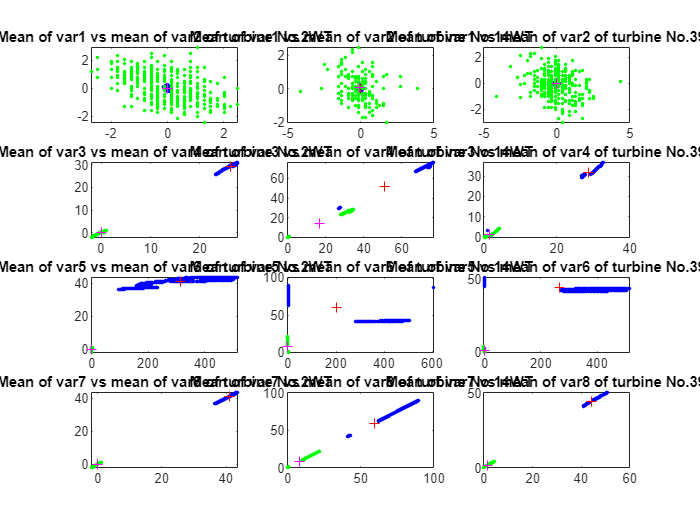

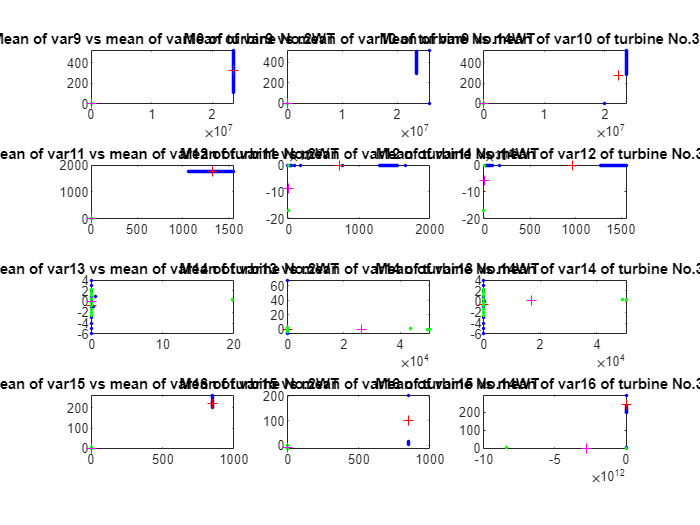

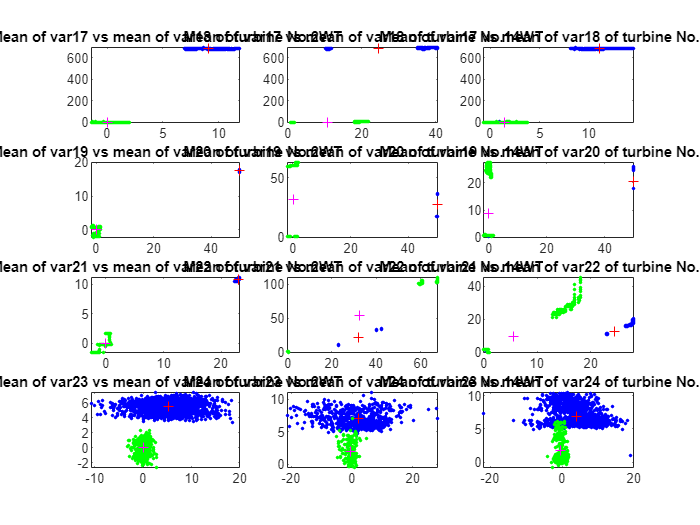

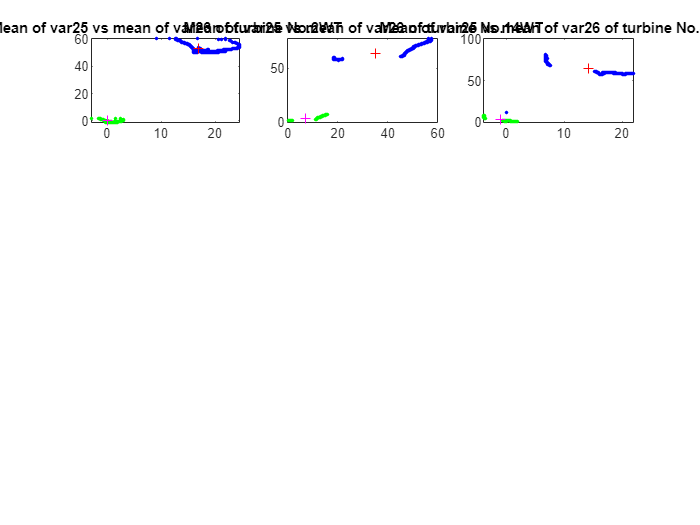

norm_down_Z = cell(numel(class_Z), 1);

% Normalize WT-2 for mean=0 and std.dev=1
[norm_down_Z{1}, mu, sigma] = zscore(down_Z{1});

% Check if any sigma == 0, add an epsilon constant term to avoid division
% by 0
epsilon = 1e-10;
zero_sigma_idx = find(sigma==0);
sigma(zero_sigma_idx) = epsilon;

for k=2:chosen_nWTs
    norm_down_Z{k} = normalize(down_Z{k}, "center", mu, "scale", sigma);
end

norm_down_meanWTs = cell(chosen_nWTs, 1);
norm_down_minWTs = cell(chosen_nWTs, 1);
norm_down_maxWTs = cell(chosen_nWTs, 1);
norm_down_stdWTs = cell(chosen_nWTs, 1);

for k=1:chosen_nWTs
    [down_rWTs(k), down_cWTs(k)] = size(down_Z{k});
    norm_down_meanWTs{k} = mean(norm_down_Z{k});
    norm_down_minWTs{k} = min(norm_down_Z{k});
    norm_down_maxWTs{k} = max(norm_down_Z{k});
    norm_down_stdWTs{k} = std(norm_down_Z{k});
end


subplot_idx = reshape(1:chosen_nWTs*4, chosen_nWTs, 4)';
count = 1;
enough = false;
for i=0:4:28
    figure;
    for r=1:4
        if (count > 27 || count + 1 > 27)
            enough = true;
            break
        end
        for k=1:chosen_nWTs
            subplot(4,chosen_nWTs,subplot_idx(r,k));
            plot(Z{k}(:,count), Z{k}(:,count+1), '.b'), hold on;
            plot(chosen_meanWTs{k}(count), chosen_meanWTs{k}(count+1), 'r+');
            plot(norm_down_Z{k}(:,count), norm_down_Z{k}(:,count+1), '.g');
            plot(norm_down_meanWTs{k}(count), norm_down_meanWTs{k}(count+1), 'm+'), hold off;
            title_text = sprintf('Mean of var%d vs mean of var%d of turbine %s', count, count+1, chosen_turbine_idx{k});
            title(title_text);
        end
        count = count + 2;
    end
    if (enough)
        break
    end
end 

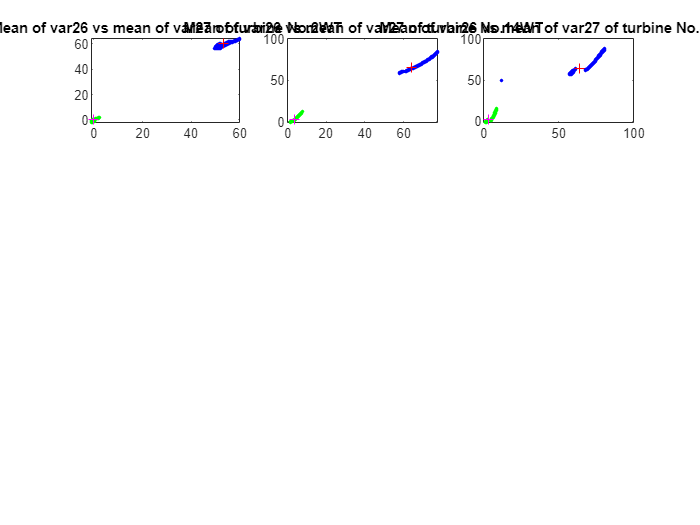


count = 26;
figure;
for k = 1:chosen_nWTs
    subplot(4,chosen_nWTs,k);
    plot(Z{k}(:,count), Z{k}(:,count+1), '.b'), hold on;
    plot(chosen_meanWTs{k}(count), chosen_meanWTs{k}(count+1), 'r+');
    plot(norm_down_Z{k}(:,count), norm_down_Z{k}(:,count+1), '.g');
    plot(norm_down_meanWTs{k}(count), norm_down_meanWTs{k}(count+1), 'm+'), hold off;
    title_text = sprintf('Mean of var%d vs mean of var%d of turbine %s', count, count+1, chosen_turbine_idx{k});
    title(title_text);
end


save norm_down_Z.mat norm_down_Z


## PCA

### Performing PCA on healthy turbine No.2WT

load norm_down_Z.mat

% Performing PCA
[PCA_coeff, PCA_score, PCA_latent, PCA_tsquare, PCA_pexp, PCA_mu] = pca(norm_down_Z{1});

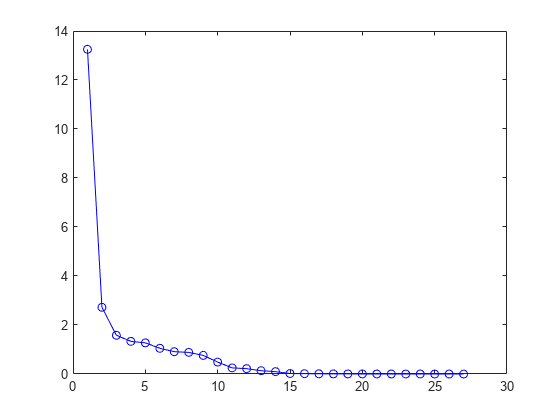


% Plot of eigenvalues
figure;
plot(1:numel(PCA_latent), PCA_latent, "-bo")

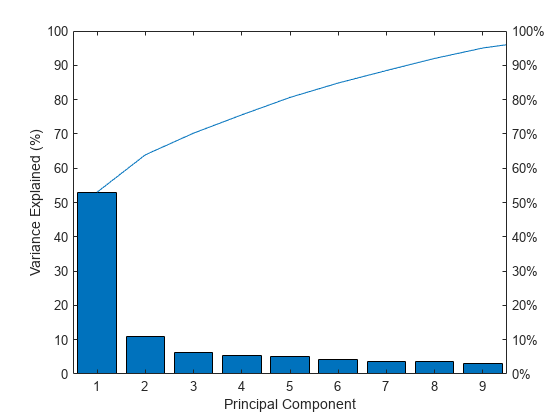


% Defining threshold for explained variance to preserve
threshold = 90;
% Getting the number of PCs to keep
chosen_nPCs = find(cumsum(PCA_pexp)>threshold, 1);
% Pareto chart of explained variance
figure;
pareto(PCA_pexp);
xlabel('Principal Component')
ylabel('Variance Explained (%)')

### Extracting/Transforming data using obtained PCA

PCA_Z = cell(chosen_nWTs, 1);

% Extracting PCA scores of healthy turbine No.2WT
PCA_Z{1} = PCA_score(:,1:chosen_nPCs);
% Transforming data of faulty turbin No.14WT
PCA_Z{2} = (norm_down_Z{2}-PCA_mu)*PCA_coeff(:,1:chosen_nPCs);
% Transforming data of faulty turbin No.39WT
PCA_Z{3} = (norm_down_Z{3}-PCA_mu)*PCA_coeff(:,1:chosen_nPCs);


### Visualization of time-series data after PCA transformation

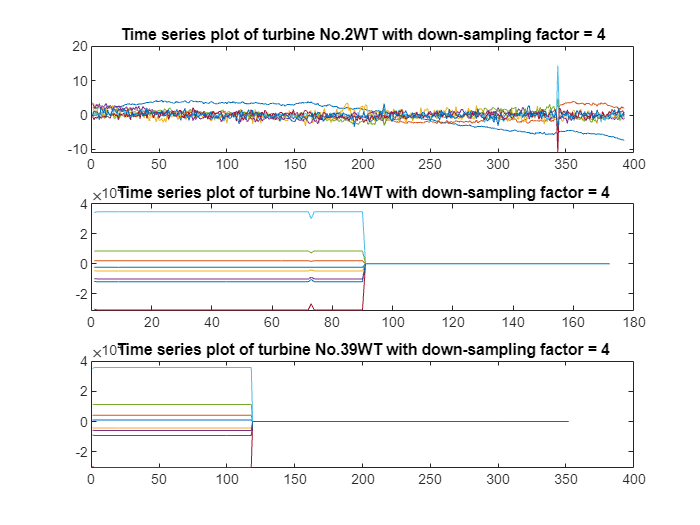

figure;
for turbine_i = 1:length(PCA_Z)
    subplot(3,1,turbine_i);
    for feature_i = 1:size(PCA_Z{turbine_i}, 2)
        nObs = size(PCA_Z{turbine_i},1);
        plot(1:nObs, PCA_Z{turbine_i}(:,feature_i)), hold on;
        title(sprintf("Time series plot of turbine %s with down-sampling factor = %d", chosen_turbine_idx{turbine_i}, downsampling_factor))
    end
    hold off
end

### Biplots

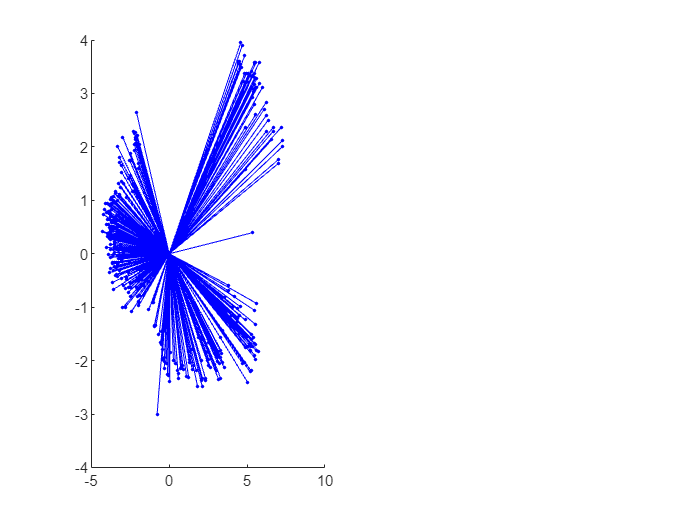

Error using biplot
'VarLabels' value must be a string array, a character array, or a cell
array of character vectors with one label for each row of the
coefficients matrix.

% Computing the biplot
subplot(1,2,1);
vbls = {'Sensor 1','Sensor 2','Sensor 3','Sensor 4','Sensor 5','Sensor 6', ...
'Sensor 7','Sensor 8','Sensor 9','Sensor 10','Sensor 11','Sensor 12', ...
'Sensor 13','Sensor 14','Sensor 15','Sensor 16','Sensor 17','Sensor 18', ...
'Sensor 19','Sensor 20','Sensor 21','Sensor 22','Sensor 23','Sensor 24', ...
'Sensor 25','Sensor 26','Sensor 27'};
biplot(PCA_score(:,1:2),'Scores',PCA_score(:,1:2),'VarLabels',vbls);


xlim([-1 1]);
ylim([-1 1]);

### T-squared control chart

% Computing T2 control chart
subplot(1,2,2);
a = 1 : length(PCA_tsquare);
plot(a, PCA_tsquare)
xlabel("Sample")
ylabel("T2 Square Scores")